%% ========================================================================
%   SECTION 1: Input signal based on the paper (two crossing chirps)
% ========================================================================

clear; close all; rng(0);

fs = 100;          % Sampling frequency 100 Hz (as in paper)
T = 14;            % Duration 14 s
t = (0:1/fs:T-1/fs)';  % Time vector

% Parameters defined in the paper

f1 = 18;  %(14~28)
k1 = (14-f1)/7;
k2 = -k1;
f2 = 14-7*k2;

% k1 = 4/7;          % chirp rate (Hz/s)
% f1 = 12;           % initial frequency of IF1 (Hz)

% Instantaneous frequencies
IF1 = k1 * t + f1;             % IF1(t) = k1 t + f1
IF2 = k2 * t + f2;    % IF2(t) = -k1 t + 14k1 + f1

% Generate the chirps
phi1 = 2*pi*cumsum(IF1)/fs;
phi2 = 2*pi*cumsum(IF2)/fs;

x1 = cos(phi1);
x2 = cos(phi2);
x_clean = x1 + x2;

% Add noise
SNR_dB = 10;     % You can change SNR here
sigma_n = sqrt(var(x_clean)/10^(SNR_dB/10));
x = x_clean + sigma_n * randn(size(x_clean));

fprintf("Signal generated: Two crossing chirps as in the paper.\n");

Signal generated: Two crossing chirps as in the paper.



%% ========================================================================
%   SECTION 2: STFT computation
% ========================================================================

winLen = 256;
hop = 16;
NFFT = 1024;      % -> 700 frequency bins
win = hann(winLen,'periodic');

[STFT, F, T_frames] = spectrogram(x, win, winLen-hop, NFFT, fs);
P = abs(STFT).^2;

[numF, numT] = size(P);
fprintf('STFT size: %d x %d (should be 700 x 1400)\n', numF, numT);

STFT size: 513 x 72 (should be 700 x 1400)



%% ========================================================================
%   SECTION 3: Iterative peak removal for noise estimation
% ========================================================================

L_med = 21;            % median window
half = (L_med-1)/2;
maxIter = 3;
alpha_init = 0.5e-1;     % loose threshold
expand_rad = 2;
kernel = ones(2*expand_rad+1);

Pworking = P;
mask_total = false(size(P));

for iter = 1:maxIter

    % Frequency-wise median filtering
    Ppad = padarray(Pworking, [half 0], 'symmetric');
    noiseMed = zeros(size(Pworking));

    for tt = 1:numT
        col = Ppad(:,tt);
        medcol = zeros(numF,1);
        for ff = 1:numF
            seg = col(ff:ff+L_med-1);
            medcol(ff) = median(seg, 'omitnan');
        end
        noiseMed(:,tt) = medcol;
    end

    noiseEst = noiseMed / log(2);
    Th_local = noiseEst * (-log(alpha_init));

    mask_iter = (P > Th_local);
    mask_dilated = conv2(double(mask_iter), kernel, 'same') > 0;

    mask_total = mask_total | mask_dilated;
    Pworking(mask_dilated) = NaN;

    fprintf('Iter %d: removed %d TF points\n', iter, nnz(mask_dilated));
end

Iter 1: removed 5626 TF points
Iter 2: removed 11201 TF points
Iter 3: removed 13980 TF points



%% ========================================================================
%   SECTION 4: Global noise estimation
% ========================================================================

P_nonpeak = P(~mask_total);

sigma2_global_mean = mean(P_nonpeak);
sigma2_global_med  = median(P_nonpeak) / log(2);

sigma2_global = sigma2_global_mean;

fprintf('Global noise estimate (mean): %.4e\n', sigma2_global);

Global noise estimate (mean): 8.3900e+00



%% ========================================================================
%   SECTION 5: Final NP threshold + detection
% ========================================================================

alpha_final = 1e-3;
Th_global = sigma2_global * (-log(alpha_final));

mask_final = (P > Th_global);
fprintf('Final detection: %d TF points\n', nnz(mask_final));

Final detection: 2671 TF points


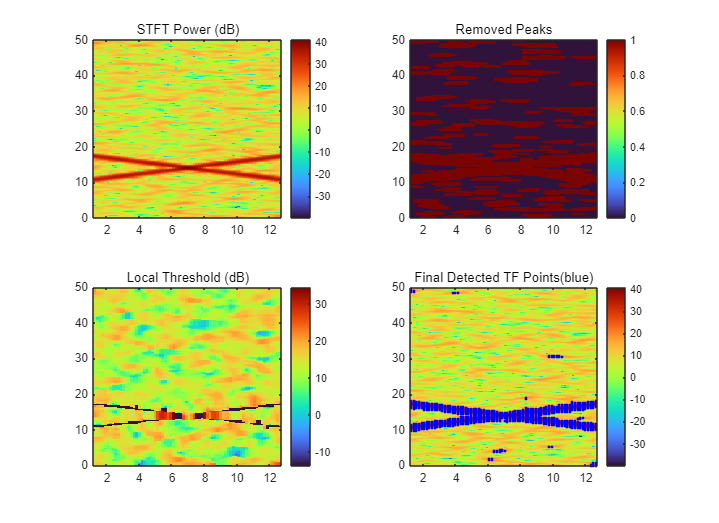


%% ========================================================================
%   SECTION 6: Visualization
% ========================================================================

figure('Position',[100 100 1100 800]);

subplot(2,2,1);
imagesc(T_frames, F, 10*log10(P+1e-12)); axis xy;
title('STFT Power (dB)'); colorbar;

subplot(2,2,2);
imagesc(T_frames, F, mask_total); axis xy;
title('Removed Peaks'); colorbar;

subplot(2,2,3);
imagesc(T_frames, F, 10*log10(Th_local+1e-12)); axis xy;
title('Local Threshold (dB)'); colorbar;

subplot(2,2,4);
imagesc(T_frames, F, 10*log10(P+1e-12)); axis xy; hold on;
[y,x_] = find(mask_final);
scatter(T_frames(x_), F(y), 5, 'b', 'filled');
title('Final Detected TF Points(blue)'); colorbar;

colormap turbo;